# **Gemelo Digital - Bicineta**

## **Minimos Cuadrados Recursivo - Modelo ARX (AutoRegressive with eXogenous inputs)**

**Entradas**

- **Acelerador -->    x1**

- **Voltaje        -->    x2**

- **Altitud        -->    x3**

**Salidas**

- **Velocidad    -->    y1**

- **Corriente     -->    y2**

% Tiempo de muestreo T = 1.4853s
% Datos para Simulink
t = linspace(0, 4860, 3273)';
x1 = [t table2array(TakeDataBicinetaPath_1_2_3(:,"Aceleracion_V_Acc_"))];
x2 = [t table2array(TakeDataBicinetaPath_1_2_3(:,"Voltaje_V_"))];
x3 = [t table2array(TakeDataBicinetaPath_1_2_3(:,"Altitud"))];

y1 = [t table2array(TakeDataBicinetaPath_1_2_3(:,"Velocidad_RPM_"))];
y2 = [t table2array(TakeDataBicinetaPath_1_2_3(:,"Corriente_A_"))];

% Codigo Matlab - Cargando datos para hallar theta

X1 = table2array(TakeDataBicinetaPath_1_2_3(:,"Aceleracion_V_Acc_"));
X2 = table2array(TakeDataBicinetaPath_1_2_3(:,"Voltaje_V_"));
X3 = table2array(TakeDataBicinetaPath_1_2_3(:,"Altitud"));

Y1 = table2array(TakeDataBicinetaPath_1_2_3(:,"Velocidad_RPM_"));
Y2 = table2array(TakeDataBicinetaPath_1_2_3(:,"Corriente_A_"));

Y = [Y1 Y2];
U = [X1 X2 X3];

theta = zeros(5,2);
P = eye(5);
Y_est = zeros(3273, 2);
%E = zeros(3273, 2);
for k = 2:3273
    H = [-Y(k-1,:) U(k-1,:)]';
    Ym = Y(k,:); % Y medido
    Ye = H'*theta; % Y estimado
    theta = theta + P*H/(1+H'*P*H)*(Ym-Ye);
    P = P-P*H*H'*P/(1+H'*P*H);
    Y_est(k-1,:) = Ye;
end


## Error de estimación

format bank
E = sqrt((1/3273)*sum((Y_est-Y).^2));
disp(E)

         19.56          1.78



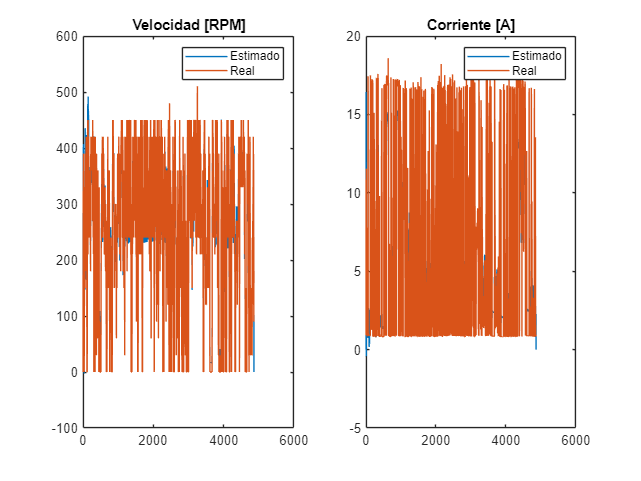

figure;
subplot(1, 2, 1)
plot(t,Y_est(:,1), t, Y(:,1))
legend('Estimado', 'Real')
title('Velocidad [RPM]')
subplot(1, 2, 2)
plot(t, Y_est(:,2), t, Y(:,2))
legend('Estimado', 'Real')
title('Corriente [A]')

## Parametros Resultantes [Velocidada, Corriente]

theta

theta =          -0.86          0.00
         -2.00         -0.68
         15.15          0.46
          0.94          0.03
         -0.03         -0.00


# **Evaluación del Modelo**

% Cargando datos de evaluación

% Entradas
X1eval = table2array(TakeDataBicinetaPath4(:, 'Aceleracion_V_Acc_'));
X2eval = table2array(TakeDataBicinetaPath4(:, 'Voltaje_V_'));
X3eval = table2array(TakeDataBicinetaPath4(:, 'Altitud'));
Ueval = [X1eval X2eval X3eval];

% Salidas
Y1eval = table2array(TakeDataBicinetaPath4(:, 'Velocidad_RPM_'));
Y2eval = table2array(TakeDataBicinetaPath4(:, 'Corriente_A_'));
Yeval = [Y1eval Y2eval];
YevalSize = size(Yeval);

tnew = linspace(0, 2640, 1806)';
YnewEst = zeros(YevalSize(1,1), 2);

for k = 2:YevalSize(1,1)
    H = [-Y(k-1,:) U(k-1,:)]';
    YnewEst(k-1, :) = H'*theta;
end

## **Error de estimación**

format bank
E = sqrt((1/1806)*sum((YnewEst-Yeval).^2));
disp(E)

        138.44          7.92



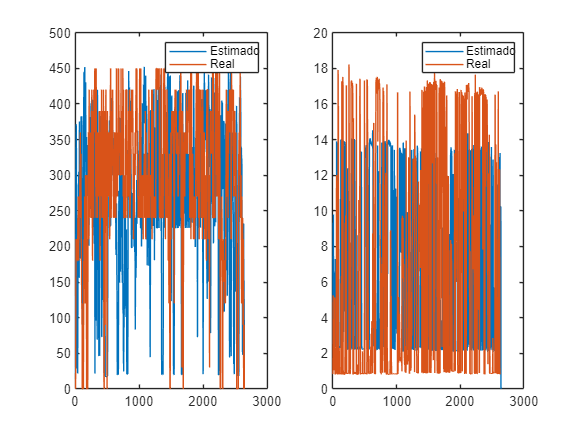

figure;
subplot(1, 2, 1)
plot(tnew,YnewEst(:,1), tnew, Yeval(:,1))
legend('Estimado', 'Real')
title('Velocidad [RPM]')
subplot(1, 2, 2)
plot(tnew, YnewEst(:,2), tnew, Yeval(:,2))
legend('Estimado', 'Real')
title('Corriente [A]')